angle = [2, 4, 6, 8, 10];
fringeCount = [4, 20, 45, 70, 95];
d = 5000;
L0 = 0.532;
n_glass = mean(((2*d-fringeCount.*L0) .* (1- cos(angle)))./(2*d*(1-cos(angle)) - fringeCount.* L0))

n_glass = 1.0116


mic_calib = 0.8969

mic_calib = 0.8969

piezo_calib = 0.1596

piezo_calib = 0.1596


slice = readtable("Task9_16.txt");
time1 = slice.Var4;
detector1 = slice.Var5;
position1 = slice.Var10 * piezo_calib + 1;
isRising = diff(position1) > 0;
position1 = position1(isRising, 1);
detector1 = detector1(isRising, 1);
time1 = time1(isRising, 1);

slice = readtable("Task9_17.txt");
time2 = slice.Var4;
detector2 = slice.Var5;
position2 = slice.Var10 * piezo_calib + 1.69;
isRising = diff(position2) > 0;
position2 = position2(isRising, 1);
detector2 = detector2(isRising, 1);
time2 = time2(isRising, 1);

slice = readtable("Task9_18.txt");
time3 = slice.Var4;
detector3 = slice.Var5;
position3 = slice.Var10 * piezo_calib + 2.72;
isRising = diff(position3) > 0;
position3 = position3(isRising, 1);
detector3 = detector3(isRising, 1);
time3 = time3(isRising, 1);

patternStartX = 0.342

patternStartX = 0.3420

patternStartY = 0.020

patternStartY = 0.0200


patternEndX = 2.249

patternEndX = 2.2490

patternEndY = 0.0199

patternEndY = 0.0199


yLine = [0.005,0.03]

yLine =     0.0050    0.0300



nFringe = 9;
% Calculate the spectral width between the marked pattern boundaries
coherenceLength = patternEndX - patternStartX

coherenceLength = 1.9070

centralWavelength = coherenceLength * 2 / nFringe

centralWavelength = 0.4238

spectralWidth = (centralWavelength ^ 2) / coherenceLength * 1000

spectralWidth = 94.1728

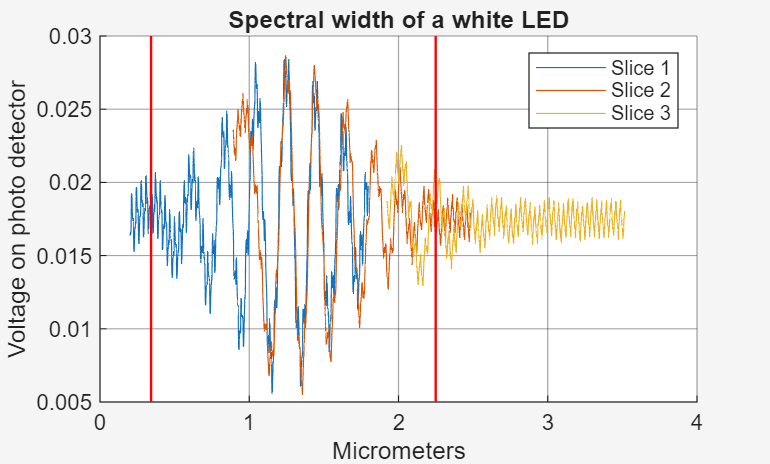


figure;
hold on;
plot(position1, detector1)
plot(position2, detector2)
plot(position3, detector3)
plot([patternStartX,patternStartX],yLine, "Color","red","LineWidth",1)
plot([patternEndX,patternEndX],yLine, "Color","red","LineWidth",1)
title("Spectral width of a white LED")
xlabel("Micrometers")
ylabel("Voltage on photo detector")
legend("Slice 1", "Slice 2", "Slice 3")
grid on
theme light;
ax = gca;
ax.GridAlpha = .4;
exportgraphics(gcf, 'white_led_spectral_width.png', 'Resolution', 300)

mic_calib = 0.8969

mic_calib = 0.8969

piezo_calib = 0.1596

piezo_calib = 0.1596

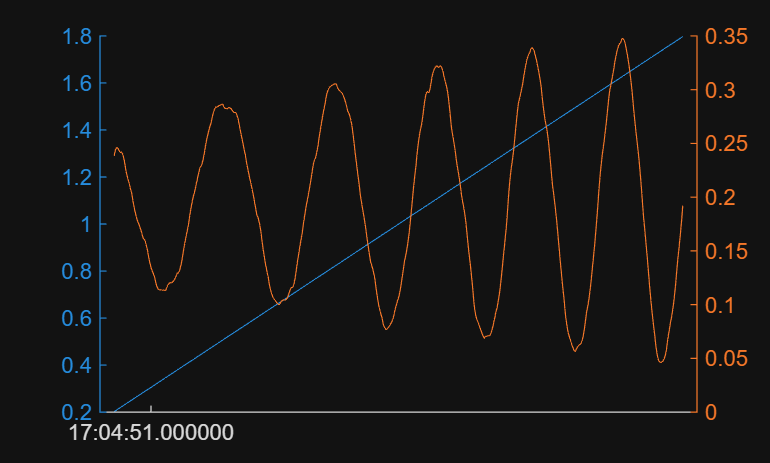


slice = readtable("Task81.txt");
time = slice.Var4;
detector = slice.Var5;
position = slice.Var10 * piezo_calib + 1;
isRising = diff(position) > 0;
position_rising = position(isRising, 1);
detector_rising = detector(isRising, 1);
time_rising = time(isRising, 1);
isFalling = diff(position) < 0;
position_falling = position(isFalling, 1);
detector_falling = detector(isFalling, 1);
time_falling = time(isFalling, 1);

figure;
hold on;
yyaxis left;
plot(time_rising, position_rising)
yyaxis right;
plot(time_rising, detector_rising)

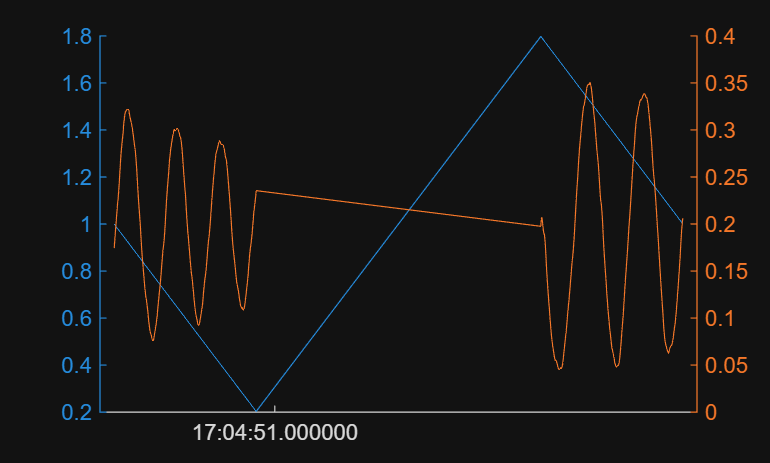


figure;
hold on;
yyaxis left;
plot(time_falling, position_falling)
yyaxis right;
plot(time_falling, detector_falling)

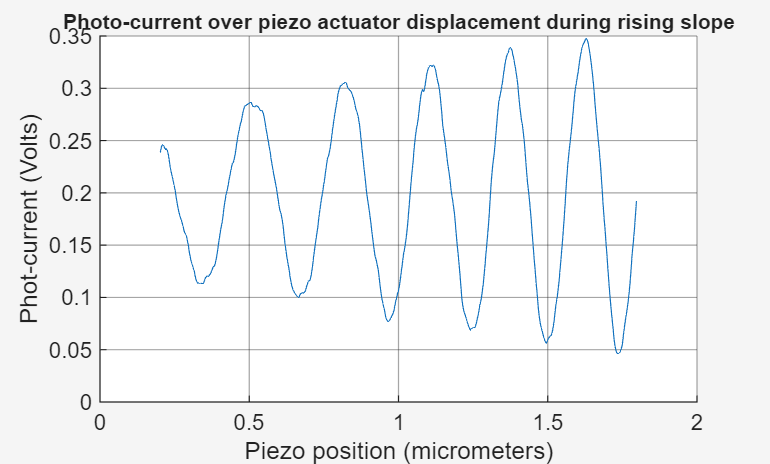


figure;
hold on;
title("Photo-current over piezo actuator displacement during rising slope","FontSize",9);
ylabel("Phot-current (Volts)");
xlabel("Piezo position (micrometers)");
plot(position_rising, detector_rising);
grid on
theme light;
ax = gca;
ax.GridAlpha = .4;
exportgraphics(gcf, 'task8_rising.png', 'Resolution', 300)

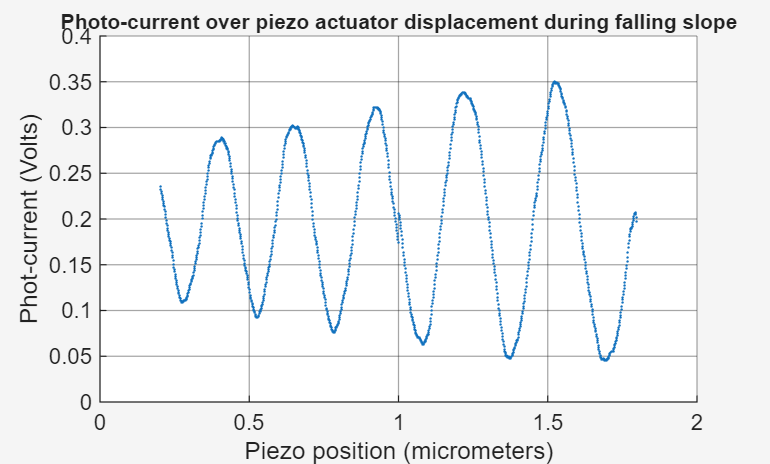


figure;
hold on;
title("Photo-current over piezo actuator displacement during falling slope","FontSize",9);
ylabel("Phot-current (Volts)");
xlabel("Piezo position (micrometers)");
plot(position_falling, detector_falling,'LineStyle','none', 'Marker','*','MarkerSize',1);
grid on
theme light;
ax = gca;
ax.GridAlpha = .4;
exportgraphics(gcf, 'task8_falling.png', 'Resolution', 300)

deltaPressure = 88;
atmPressure = 101.3;
dCell = 3 * 1000;

p_cell_kPa = [20, 32, 40, 48, 54, 59];
N = [6, 10, 14, 16, 18,20];

nDif = N * L0 / (2*dCell);
n = 1 + nDif;

fit = polyfit(p_cell_kPa,n,1);
slope = fit(1)

slope = 3.1714e-05

x0 = fit(2);

p = linspace(0,atmPressure,100);

nAir = x0 + slope * atmPressure

nAir = 1.0031

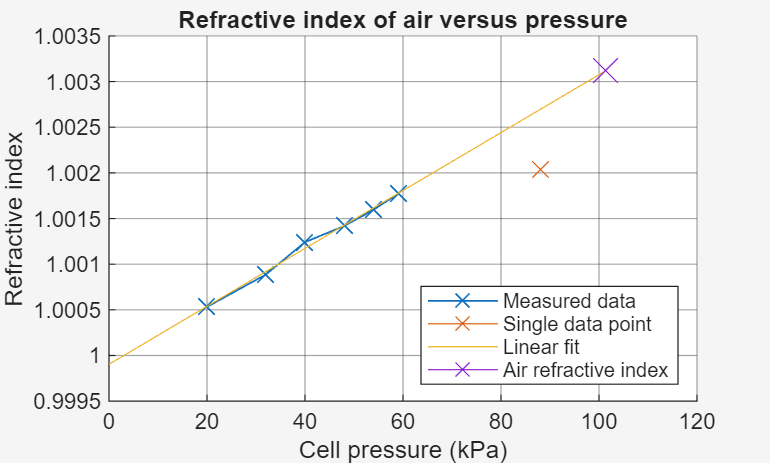


nOur = 1 + (23 * L0 / (2*dCell));
pOur = 88;

figure;
hold on;
plot(p_cell_kPa,n,'Marker','x','MarkerSize',10,'LineWidth',0.75)
plot(pOur,nOur,'Marker','x','MarkerSize',10)
plot(p, x0 + p*slope)
plot(atmPressure, nAir,'Marker','x','MarkerSize',15)
title("Refractive index of air versus pressure")
xlabel("Cell pressure (kPa)")
ylabel("Refractive index")
legend("Measured data","Single data point", "Linear fit", "Air refractive index", "Location", "southeast")
grid on
theme light;
ax = gca;
ax.GridAlpha = .4;
exportgraphics(gcf, 'pressure_refractive_index.png', 'Resolution', 300)